## Deliverable 1

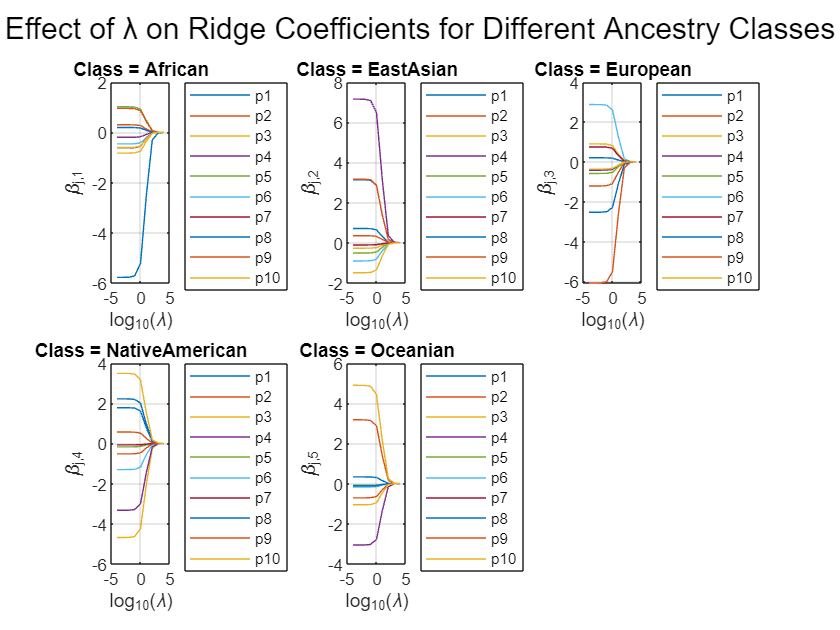

% Define the number of rows and columns for subplots
numRows = 2; % Change as needed
numCols = 3; % Change as needed

% Loop over each ancestry class
for k = 1:K
    % Create a subplot
    subplot(numRows, numCols, k);
    
    % Loop over each feature
    for j = 2:p+1
        plot(log10(lambda_values), squeeze(beta_hats(j, k, :)), '-', 'DisplayName', ['p', num2str(j-1)]);
        hold on;
    end
    
    % Labeling axes and title
    xlabel('log_{10}(\lambda)');
    ylabel(['\beta_{j,' num2str(k) '}']);
    title(['Class = ' ancestry_labels{k}]);
    legend('show', 'Location','eastoutside');
    grid on;
end

% Adjust layout for better visualization
sgtitle('Effect of λ on Ridge Coefficients for Different Ancestry Classes');

## Deliverable 2

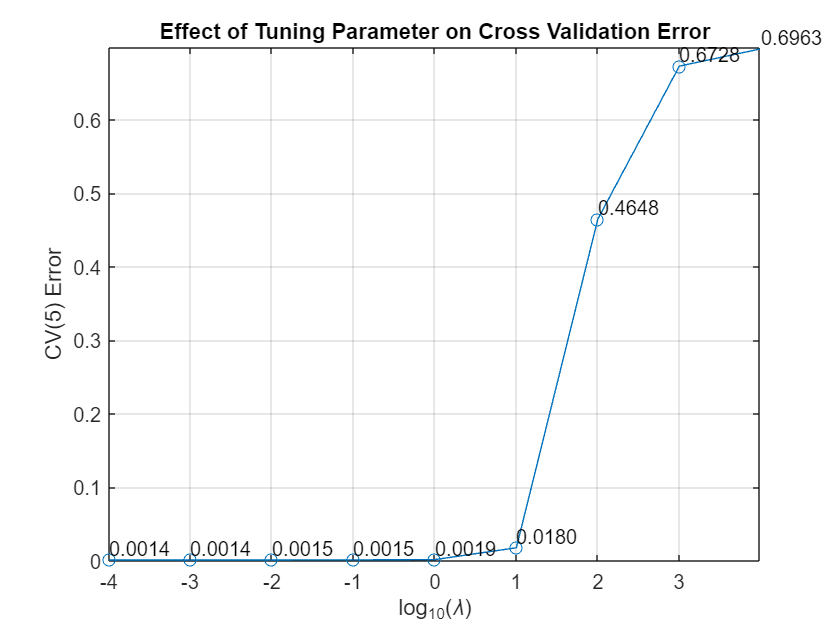

% Plotting the cross-validation errors vs log10 tuning parameter values
figure;
plot(log10(lambda_values), cv_errors, '-o');
xlabel('log_{10}(\lambda)'); 
ylabel('CV(5) Error');
title('Effect of Tuning Parameter on Cross Validation Error');
grid on;

% Add text annotations for cv_errors values
for i = 1:length(lambda_values)
    text(log10(lambda_values(i)), cv_errors(i), sprintf('%.4f', cv_errors(i)), 'VerticalAlignment', 'bottom');
end

## Deliverable 3

% Display results
fprintf('The value of 𝜆 that generated the smallest CV(5) error is: %f\n', best_lambda);

The value of 𝜆 that generated the smallest CV(5) error is: 0.000100


fprintf('The corresponding minimum CV(5) error is: %f\n', min_cv_error);

The corresponding minimum CV(5) error is: 0.001446


## Deliverable 4

% Assuming you have the test labels available in test_labels
sample_labels = table2array(test_df(:, 11));

% Initialize a table to store the results
result_table = table('Size', [height(testX), 8], 'VariableTypes', {'double', 'cell', 'double', 'double', 'double', 'double', 'double', 'cell'}, ...
    'VariableNames', {'Test_Individual', 'Sample', 'African_P', 'EastAsian_P', 'European_P', 'NativeAmerican_P', 'Oceanian_P', 'Most_Probable_Ancestry_Label'});

% Report all six values for all test individuals
for i = 1:height(testX)
    % Add test individual index to the table
    result_table.Test_Individual(i) = i;
    
    % Add class probabilities to the table
    result_table.African_P(i) = Ptest(i, 1);
    result_table.EastAsian_P(i) = Ptest(i, 2);
    result_table.European_P(i) = Ptest(i, 3);
    result_table.NativeAmerican_P(i) = Ptest(i, 4);
    result_table.Oceanian_P(i) = Ptest(i, 5);
    
    % Add predicted label to the table
    result_table.Most_Probable_Ancestry_Label(i) = {ancestry_labels{predicted_labels(i)}};
    
    % Add true label to the table
    result_table.Sample(i) = sample_labels(i, 1);
end

% Display the resulting table
disp(result_table);

    Test_Individual          Sample           African_P     EastAsian_P    European_P    NativeAmerican_P    Oceanian_P    Most_Probable_Ancestry_Label
    _______________    ___________________    __________    ___________    __________    ________________    __________    ____________________________

            1          {'Unknown'        }    2.9843e-09    1.3499e-21     4.7145e-15       1.1329e-22                1         {'Oceanian'      }     
            2          {'Unknown'        }    7.9962e-10    3.2422e-22     2.4451e-12          0.99949       3.4818e-24         {'NativeAmerican'}     
            3          {'Unknown'        }    7.5202e-10     2.471e-16       0.065895       2.3457e-19       1.2961e-21


% Use writetable to save the table to Excel
writetable(result_table, 'deliverable_4.xlsx');